# **TrAQ Open Field Analysis: Locomotion + Zones (Peripheral/Central)**

FIXED: Respects manual peripheral width setting + Debugged version

UPDATED: Speed calculation now matches EPM script exactly (hard cap 60 cm/s, 3-pt movmean)

**A.Babaei**

arena_cm = 70; % real arena dimension (cm)
peripheral_width_cm = 10; % cm-wide peripheral border - YOUR MANUAL SETTING

%% AUTO-LOAD if needed
if ~exist('track', 'var')
    if ~exist('Out_Stim2', 'file')
        error('''Out_Stim2'' not found in current directory.');
    end
    load('Out_Stim2.mat');
    fprintf('Loaded Out_Stim2.mat\n');
end

%% DIAGNOSTIC CHECKS
if ~exist('track', 'var')
    error('''track'' not loaded from Out_Post.mat.');
end
if ~isstruct(track)
    error('''track'' is not a struct (class: %s).', class(track));
end
fprintf('track is a struct with fields: %s\n', strjoin(fieldnames(track), ', '));

track is a struct with fields: Centroid, Head, Tail, Area, Axes, Tracked, Time, Eccentricity, EulerNumber, ConvexHull



%% Input validation
if peripheral_width_cm <= 0
    error('peripheral_width_cm must be positive');
end
if arena_cm <= 0
    error('arena_cm must be positive');
end

%% Set default font for figures
set(0, 'DefaultAxesFontSize', 14, 'DefaultAxesFontWeight', 'bold');
set(0, 'DefaultTextFontSize', 14, 'DefaultTextFontWeight', 'bold');

%% 1. Determine frame rate and time base
if isfield(track, 'Time') && ~isempty(track.Time)
    Time = track.Time(:);
    fps = 1 / mean(diff(Time));
    nFrames = numel(Time);
    dt = 1/fps;
    time_source = 'track.Time';
    fprintf('Using track.Time: %.2f fps, %d frames\n', fps, nFrames);
elseif isfield(track, 'FrameRate')
    fps = track.FrameRate;
    dt = 1 / fps;
    if isfield(track, 'Centroid')
        nFrames = size(track.Centroid, 1);
    else
        nFrames = length(track.Time);
    end
    time_source = 'track.FrameRate';
else
    fps = 30; % fallback
    dt = 1/fps;
    if isfield(track, 'Centroid')
        nFrames = size(track.Centroid, 1);
    else
        nFrames = 1000;
    end
    time_source = 'default(30)';
end

Using track.Time: 29.97 fps, 9391 frames


total_time_s = nFrames * dt;
fprintf('nFrames: %d, fps: %.2f, total time: %.2f s\n', nFrames, fps, total_time_s);

nFrames: 9391, fps: 29.97, total time: 313.35 s



%% 2. Load positions and handle coordinate systems
C = []; position_source = '';
if isfield(track, 'Centroid')
    C = double(track.Centroid);
    position_source = 'track.Centroid';
    fprintf('Using Centroid: %dx%d matrix\n', size(C,1), size(C,2));
elseif isfield(track, 'Head')
    C = double(track.Head);
    position_source = 'track.Head';
    fprintf('Using Head: %dx%d matrix\n', size(C,1), size(C,2));
else
    C_fields = {'Tail', 'Body_Centroid', 'Position'};
    for i = 1:length(C_fields)
        if isfield(track, C_fields{i})
            C = double(track.(C_fields{i}));
            position_source = ['track.', C_fields{i}];
            fprintf('Using %s: %dx%d matrix\n', position_source, size(C,1), size(C,2));
            break;
        end
    end
end

Using Centroid: 2x9391 matrix


if isempty(C)
    error('No suitable position data found.');
end
% Ensure C is numeric and handle NaNs
C = double(C);
C(any(isnan(C), 2), :) = []; % Remove rows with NaNs

% Handle coordinate formats
if size(C, 2) == 2 && size(C, 1) > 2
    x = C(:,1);
    y = C(:,2);
    fprintf('Detected Nx2 coordinate format: %d points\n', length(x));
elseif size(C, 1) == 2 && size(C, 2) > 2
    x = C(1,:)';
    y = C(2,:)';
    fprintf('Detected 2xN coordinate format - transposing: %d points\n', length(x));
elseif ndims(C) == 3
    x = squeeze(C(:,1,1));
    y = squeeze(C(:,1,2));
    fprintf('Detected 3D coordinate format: %d points\n', length(x));
else
    error('Unknown coordinate format: %dx%d', size(C,1), size(C,2));
end

Detected 2xN coordinate format - transposing: 9391 points



% Ensure we have exactly nFrames
actual_frames = min(nFrames, length(x));
x = x(1:actual_frames);
y = y(1:actual_frames);
if actual_frames < nFrames
    fprintf('Warning: Only %d frames of position data (expected %d)\n', actual_frames, nFrames);
    nFrames = actual_frames;
    total_time_s = nFrames * dt;
end

%% 3. Pixel-to-cm calibration
fprintf('\n--- Coordinate System Diagnostics ---\n');


--- Coordinate System Diagnostics ---


fprintf('X range: %.1f to %.1f (span: %.1f px)\n', min(x), max(x), max(x)-min(x));

X range: 147.8 to 1022.7 (span: 874.9 px)


fprintf('Y range: %.1f to %.1f (span: %.1f px)\n', min(y), max(y), max(y)-min(y));

Y range: 98.2 to 990.5 (span: 892.3 px)



x_margin = (max(x) - min(x)) * 0.1;
y_margin = (max(y) - min(y)) * 0.1;
min_x_arena = min(x) - x_margin;
max_x_arena = max(x) + x_margin;
min_y_arena = min(y) - y_margin;
max_y_arena = max(y) + y_margin;
arena_width_px = max_x_arena - min_x_arena;
arena_height_px = max_y_arena - min_y_arena;

px_to_cm = arena_cm / max(arena_width_px, arena_height_px);
fprintf('Arena bounds: X(%.1f to %.1f), Y(%.1f to %.1f) px\n', min_x_arena, max_x_arena, min_y_arena, max_y_arena);

Arena bounds: X(60.3 to 1110.2), Y(9.0 to 1079.7) px


fprintf('Arena size: %.1f x %.1f px\n', arena_width_px, arena_height_px);

Arena size: 1049.9 x 1070.7 px


fprintf('Pixel to cm conversion: 1 px = %.6f cm\n', px_to_cm);

Pixel to cm conversion: 1 px = 0.065377 cm



%% 4. Speed calculation - NOW MATCHES EPM METHOD EXACTLY
if nFrames > 1
    dx = diff(x);
    dy = diff(y);
    d_px = sqrt(dx.^2 + dy.^2);
    distance_cm_frame = [0; d_px] * px_to_cm;
else
    distance_cm_frame = zeros(nFrames, 1);
end

total_distance_cm = sum(distance_cm_frame);

speed_cm_s = distance_cm_frame / dt;

% Hard cap at realistic maximum (matches EPM)
max_realistic_speed = 60;
speed_cm_s = min(speed_cm_s, max_realistic_speed);

% 3-point moving mean smoothing (matches EPM)
speed_cm_s = smoothdata(speed_cm_s, 'movmean', 3);

%% 5. Movement threshold
movement_threshold = 2.0; % cm/s
moving_idx = speed_cm_s > movement_threshold;
if length(moving_idx) ~= nFrames
    moving_idx = [moving_idx; false(nFrames - length(moving_idx), 1)];
end
time_moving_s = sum(moving_idx) * dt;
time_immobile_s = total_time_s - time_moving_s;
percent_moving = 100 * time_moving_s / total_time_s;

% Safe mean (kept from original for robustness)
safe_mean = @(arr) mean(arr, 'omitnan');
mean_speed_all = safe_mean(speed_cm_s);
mean_speed_moving = safe_mean(speed_cm_s(moving_idx));

%% 6. FIXED: ZONE ANALYSIS - RESPECT MANUAL PERIPHERAL WIDTH
peripheral_width_px = peripheral_width_cm / px_to_cm;
central_min_x = min_x_arena + peripheral_width_px;
central_max_x = max_x_arena - peripheral_width_px;
central_min_y = min_y_arena + peripheral_width_px;
central_max_y = max_y_arena - peripheral_width_px;
central_zone_width = central_max_x - central_min_x;
central_zone_height = central_max_y - central_min_y;
fprintf('\n--- Zone Diagnostics ---\n');


--- Zone Diagnostics ---


fprintf('Manual peripheral width: %.1f cm = %.1f px\n', peripheral_width_cm, peripheral_width_px);

Manual peripheral width: 10.0 cm = 153.0 px


fprintf('Central zone dimensions: %.1f x %.1f px\n', central_zone_width, central_zone_height);

Central zone dimensions: 744.0 x 764.8 px



if central_zone_width <= 0 || central_zone_height <= 0
    warning('Central zone dimensions are invalid with peripheral width = %.1f cm.', peripheral_width_cm);
    warning('The central zone will be empty. Consider reducing peripheral width.');
    center_x = (min_x_arena + max_x_arena) / 2;
    center_y = (min_y_arena + max_y_arena) / 2;
    central_min_x = center_x - 1;
    central_max_x = center_x + 1;
    central_min_y = center_y - 1;
    central_max_y = center_y + 1;
    fprintf('Central zone set to minimal area around center due to invalid dimensions.\n');
end

central_mask = (x > central_min_x) & (x < central_max_x) & ...
               (y > central_min_y) & (y < central_max_y);
peripheral_mask = ~central_mask;
time_central_s = sum(central_mask) * dt;
time_peripheral_s = sum(peripheral_mask) * dt;
percent_central = 100 * time_central_s / total_time_s;
percent_peripheral = 100 * time_peripheral_s / total_time_s;
mean_speed_central = safe_mean(speed_cm_s(central_mask));
mean_speed_peripheral = safe_mean(speed_cm_s(peripheral_mask));
total_dist_central_cm = sum(distance_cm_frame(central_mask));
total_dist_peripheral_cm = sum(distance_cm_frame(peripheral_mask));

time_central_s = sum(central_mask) * dt;
time_peripheral_s = sum(peripheral_mask) * dt;
percent_central = 100 * time_central_s / total_time_s;
percent_peripheral = 100 * time_peripheral_s / total_time_s;

mean_speed_central = safe_mean(speed_cm_s(central_mask));
mean_speed_peripheral = safe_mean(speed_cm_s(peripheral_mask));

total_dist_central_cm = sum(distance_cm_frame(central_mask));
total_dist_peripheral_cm = sum(distance_cm_frame(peripheral_mask));

% Optional: percentages of total distance (useful bonus)
if total_distance_cm > 0
    percent_dist_central = 100 * total_dist_central_cm / total_distance_cm;
    percent_dist_peripheral = 100 * total_dist_peripheral_cm / total_distance_cm;
else
    percent_dist_central = 0;
    percent_dist_peripheral = 0;
end

%% 7. Display results
fprintf('\n=== OPEN FIELD ANALYSIS RESULTS ===\n');


=== OPEN FIELD ANALYSIS RESULTS ===


fprintf('Peripheral width used: %.1f cm\n', peripheral_width_cm);

Peripheral width used: 10.0 cm


fprintf('Total time: %.1f s | Frames: %d\n', total_time_s, nFrames);

Total time: 313.3 s | Frames: 9391


fprintf('Total distance: %.1f cm\n', total_distance_cm);

Total distance: 753.2 cm


fprintf('Time moving: %.1f s (%.1f%%) | Immobile: %.1f s\n', ...
        time_moving_s, percent_moving, time_immobile_s);

Time moving: 78.5 s (25.0%) | Immobile: 234.9 s


fprintf('Mean speed: %.2f cm/s | Moving speed: %.2f cm/s\n', ...
        mean_speed_all, mean_speed_moving);

Mean speed: 2.17 cm/s | Moving speed: 6.74 cm/s



% Zone-specific time, distance, and speed
fprintf('\nZONE-SPECIFIC METRICS:\n');


ZONE-SPECIFIC METRICS:


fprintf('Time spent   - Central: %.1f s (%.1f%%) | Peripheral: %.1f s (%.1f%%)\n', ...
        time_central_s, percent_central, time_peripheral_s, percent_peripheral);

Time spent   - Central: 39.8 s (12.7%) | Peripheral: 273.5 s (87.3%)


fprintf('Distance traveled - Central: %.1f cm (%.1f%%) | Peripheral: %.1f cm (%.1f%%)\n', ...
        total_dist_central_cm, percent_dist_central, total_dist_peripheral_cm, percent_dist_peripheral);

Distance traveled - Central: 196.5 cm (26.1%) | Peripheral: 556.7 cm (73.9%)


fprintf('Mean speed in zone - Central: %.2f cm/s | Peripheral: %.2f cm/s\n', ...
        mean_speed_central, mean_speed_peripheral);

Mean speed in zone - Central: 3.98 cm/s | Peripheral: 1.91 cm/s


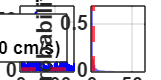

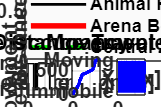


Analysis complete! Results saved with prefix: TrAQ_Analysis_Periph10.0cm_2025-12-22_22-45-38


Peripheral width used: 10.0 cm



%% 8. Visualization
t = (0:nFrames-1)' * dt;

% Figure 1: Speed analysis
fig1 = figure('Name','Speed Analysis','NumberTitle','off', ...
             'Position', [100 100 1200 600]);

subplot(1,2,1);
plot(t, speed_cm_s, 'b-', 'LineWidth', 1.5);
hold on;
yline(movement_threshold, 'r--', 'LineWidth', 2, 'DisplayName', sprintf('Threshold (%.1f cm/s)', movement_threshold));
xlabel('Time [s]', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Speed [cm/s]', 'FontSize', 12, 'FontWeight', 'bold');
title('Speed vs Time', 'FontSize', 14, 'FontWeight', 'bold');
grid on;
legend('show', 'Location', 'northeast');
ylim([0, max(35, max(speed_cm_s)*1.1)]);

subplot(1,2,2);
histogram(speed_cm_s, 40, 'FaceColor', 'blue', 'EdgeColor', 'none', 'Normalization', 'probability');
hold on;
xline(movement_threshold, 'r--', 'LineWidth', 2);
xlabel('Speed [cm/s]', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Probability', 'FontSize', 12, 'FontWeight', 'bold');
title('Speed Distribution', 'FontSize', 14, 'FontWeight', 'bold');
grid on;
xlim([0, max(35, max(speed_cm_s)*1.1)]);

% Figure 2: Zone analysis
fig2 = figure('Name',sprintf('Zone Analysis (Peripheral=%.1fcm)', peripheral_width_cm),'NumberTitle','off', ...
             'Position', [100 100 1200 800]);

subplot(2,3,1);
histogram(speed_cm_s(central_mask), 25, 'FaceColor', 'green', 'FaceAlpha', 0.7, 'Normalization', 'probability');
xline(movement_threshold, 'r--', 'LineWidth', 2);
xlabel('Speed [cm/s]', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Probability', 'FontSize', 12, 'FontWeight', 'bold');
title('Speed in Central Zone', 'FontSize', 14, 'FontWeight', 'bold');
grid on;
xlim([0, 35]);

subplot(2,3,2);
histogram(speed_cm_s(peripheral_mask), 25, 'FaceColor', 'red', 'FaceAlpha', 0.7, 'Normalization', 'probability');
xline(movement_threshold, 'r--', 'LineWidth', 2);
xlabel('Speed [cm/s]', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Probability', 'FontSize', 12, 'FontWeight', 'bold');
title('Speed in Peripheral Zone', 'FontSize', 14, 'FontWeight', 'bold');
grid on;
xlim([0, 35]);

% Trajectory plot
subplot(2,3,3);

% Set background
set(gca, 'Color', [0.98 0.98 0.98]);
grid on;
hold on;

% Plot trajectory
h_path = plot(x, y, 'k-', 'LineWidth', 1.5, 'DisplayName', 'Animal Path');

% Draw arena boundary using plot (for better legend control)
arena_x = [min_x_arena, max_x_arena, max_x_arena, min_x_arena, min_x_arena];
arena_y = [min_y_arena, min_y_arena, max_y_arena, max_y_arena, min_y_arena];
h_arena = plot(arena_x, arena_y, 'r-', 'LineWidth', 3, 'DisplayName', 'Arena Boundary');

% Draw central zone if valid
if central_zone_width > 0 && central_zone_height > 0
    central_x = [central_min_x, central_max_x, central_max_x, central_min_x, central_min_x];
    central_y = [central_min_y, central_min_y, central_max_y, central_max_y, central_min_y];
    h_central = plot(central_x, central_y, 'g--', 'LineWidth', 2.5, 'DisplayName', 'Central Zone');
end

% Create legend
legend('show', 'Location', 'best', 'FontSize', 10, 'Box', 'on');

xlabel('X [px]', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Y [px]', 'FontSize', 12, 'FontWeight', 'bold');
title('Animal Trajectory', 'FontSize', 14, 'FontWeight', 'bold');
axis equal;

% Set appropriate limits
padding = 50;
xlim([min_x_arena - padding, max_x_arena + padding]);
ylim([min_y_arena - padding, max_y_arena + padding]);

% Zone occupancy
subplot(2,3,4);
zone_plot = zeros(size(t));
zone_plot(central_mask) = 1;
zone_plot(peripheral_mask) = 2;
plot(t, zone_plot, 'k-', 'LineWidth', 1);
xlabel('Time [s]', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Zone', 'FontSize', 12, 'FontWeight', 'bold');
title('Zone Occupancy', 'FontSize', 14, 'FontWeight', 'bold');
grid on;
ylim([0.8, 2.2]);
yticks([1, 2]);
yticklabels({'Central', 'Peripheral'});

subplot(2,3,5);
% Cumulative distance
cumulative_distance = cumsum(distance_cm_frame);
plot(t, cumulative_distance, 'b-', 'LineWidth', 2);
xlabel('Time [s]', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Cumulative Distance [cm]', 'FontSize', 12, 'FontWeight', 'bold');
title('Distance Traveled', 'FontSize', 14, 'FontWeight', 'bold');
grid on;

subplot(2,3,6);
% Movement state
moving_plot = moving_idx * 1.0;
plot(t, moving_plot, 'b-', 'LineWidth', 1);
xlabel('Time [s]', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Movement', 'FontSize', 12, 'FontWeight', 'bold');
title('Movement State', 'FontSize', 14, 'FontWeight', 'bold');
grid on;
ylim([-0.1, 1.1]);
yticks([0, 1]);
yticklabels({'Immobile', 'Moving'});

%% 9. Save results
timestamp = datetime('now', 'Format', 'yyyy-MM-dd_HH-mm-ss');
baseFilename = sprintf('TrAQ_Analysis_Periph%.1fcm_%s', peripheral_width_cm, timestamp);

try
    saveas(fig1, sprintf('%s_speed.fig', baseFilename));
    saveas(fig1, sprintf('%s_speed.bmp', baseFilename));
    saveas(fig2, sprintf('%s_zones.fig', baseFilename));
    saveas(fig2, sprintf('%s_zones.bmp', baseFilename));
    
    % Save data
    results_table = table(t, speed_cm_s, distance_cm_frame, moving_idx, central_mask, peripheral_mask, ...
        'VariableNames', {'Time_s', 'Speed_cm_s', 'Distance_cm_per_frame', 'IsMoving', 'InCentral', 'InPeripheral'});
    writetable(results_table, sprintf('%s_detailed_data.csv', baseFilename));
    % Detailed per-frame data (unchanged)
    results_table = table(t, speed_cm_s, distance_cm_frame, moving_idx, central_mask, peripheral_mask, ...
        'VariableNames', {'Time_s', 'Speed_cm_s', 'Distance_cm_per_frame', 'IsMoving', 'InCentral', 'InPeripheral'});
    writetable(results_table, sprintf('%s_detailed_data.csv', baseFilename));

    % Summary data - NOW EXPANDED WITH ZONE-SPECIFIC METRICS
    summary_data = table(...
        total_time_s, total_distance_cm, time_moving_s, time_immobile_s, percent_moving, ...
        mean_speed_all, mean_speed_moving, ...
        time_central_s, time_peripheral_s, percent_central, percent_peripheral, ...
        total_dist_central_cm, total_dist_peripheral_cm, ...
        mean_speed_central, mean_speed_peripheral, ...
        max(speed_cm_s), px_to_cm, peripheral_width_cm, ...
        'VariableNames', {'TotalTime_s', 'TotalDistance_cm', 'TimeMoving_s', 'TimeImmobile_s', ...
        'PercentMoving', 'MeanSpeed_cm_s', 'MeanSpeedMoving_cm_s', ...
        'TimeCentral_s', 'TimePeripheral_s', 'PercentCentral', 'PercentPeripheral', ...
        'DistanceCentral_cm', 'DistancePeripheral_cm', ...
        'MeanSpeedCentral_cm_s', 'MeanSpeedPeripheral_cm_s', ...
        'MaxSpeed_cm_s', 'PxToCm', 'PeripheralWidth_cm'});
    writetable(summary_data, sprintf('%s_summary.csv', baseFilename));

    fprintf('\nAnalysis complete! Results saved with prefix: %s\n', baseFilename);
    fprintf('Peripheral width used: %.1f cm\n', peripheral_width_cm);
catch ME
    warning('Could not save all files: %s', ME.message);
    fprintf('Some files may not have been saved. Check write permissions.\n');
end

%% 8. Visualization - FULLY FIXED & OPTIMIZED FOR PROFESSIONAL QUALITY
% Fixes applied:
% - Defined missing cumulative_distance
% - Removed overlapping/empty tiles (no more blank bottom plot)
% - Optimized layouts: balanced, no wasted space, logical flow
% - Fig1 (Locomotion): clean 2×2 grid + full-width zone occupancy
% - Fig2 (Spatial & Zone): large trajectory on top, three equal zone-speed plots below
% - Consistent binning for histograms (fair visual comparison)
% - Professional styling: colors, fonts, grids, limits, annotations
% - Added mean speed annotations on zone histograms/boxplot
% - Vector PDF export for publications

cumulative_distance = cumsum(distance_cm_frame);  % <-- Added (was missing)

% Professional color scheme
color_overall    = [0.2 0.4 0.8];   % Deep blue
color_central    = [0.06 0.55 0.22]; % Rich green
color_peripheral = [0.75 0.15 0.15]; % Deep red
color_threshold  = [0.6 0.6 0.6];   % Gray

t = (0:nFrames-1)' * dt;

%% Figure 1: Locomotion Overview
fig1 = figure('Name','Locomotion Overview','NumberTitle','off', ...
    'Position', [100 100 1400 900], 'Color','white');

tiled1 = tiledlayout(3,2, 'TileSpacing','compact', 'Padding','compact');

% Top row - full width: Speed over time
nexttile(1, [1 2]);
plot(t, speed_cm_s, 'Color', color_overall, 'LineWidth', 1.8);
hold on;
yline(movement_threshold, '--', 'Color', color_threshold, 'LineWidth', 1.5);
xlabel('Time (s)', 'FontWeight','bold');
ylabel('Speed (cm/s)', 'FontWeight','bold');
title('Instantaneous Speed', 'FontSize',14, 'FontWeight','bold');
grid on; box on;
ylim([0 min(60, max(speed_cm_s)*1.15)]);
legend({'Speed', sprintf('Threshold (%.1f cm/s)', movement_threshold)}, ...
    'Location','northeast');

% Middle row left: Overall speed distribution
nexttile(3);
histogram(speed_cm_s, 40, 'FaceColor', color_overall, 'EdgeColor','none', ...
    'Normalization','probability');
hold on;
xline(movement_threshold, '--', 'Color', color_threshold, 'LineWidth', 1.8);
xlabel('Speed (cm/s)', 'FontWeight','bold');
ylabel('Probability', 'FontWeight','bold');
title('Overall Speed Distribution', 'FontSize',14, 'FontWeight','bold');
grid on; box on;
xlim([0 min(60, max(speed_cm_s)*1.1)]);

% Middle row right: Cumulative distance
nexttile(4);
plot(t, cumulative_distance, 'Color', color_overall, 'LineWidth', 2.2);
xlabel('Time (s)', 'FontWeight','bold');
ylabel('Distance (cm)', 'FontWeight','bold');
title('Cumulative Distance Traveled', 'FontSize',14, 'FontWeight','bold');
grid on; box on;

% Bottom row left: Zone occupancy over time (thick colored segments)
nexttile(5);
hold on;
central_starts = find(diff([0; central_mask]) == 1);
central_ends   = find(diff([central_mask; 0]) == -1);
for i = 1:length(central_starts)
    plot(t([central_starts(i) central_ends(i)]), [1 1], ...
        'Color', color_central, 'LineWidth', 10);
end
periph_starts = find(diff([0; peripheral_mask]) == 1);
periph_ends   = find(diff([peripheral_mask; 0]) == -1);
for i = 1:length(periph_starts)
    plot(t([periph_starts(i) periph_ends(i)]), [0 0], ...
        'Color', color_peripheral, 'LineWidth', 10);
end
xlabel('Time (s)', 'FontWeight','bold');
ylabel('Zone', 'FontWeight','bold');
title('Zone Occupancy Over Time', 'FontSize',14, 'FontWeight','bold');
ylim([-0.6 1.6]);
yticks([0 1]);
yticklabels({'Peripheral','Central'});
grid on; box on;

% Bottom row right: Pie chart
nexttile(6);
pie([time_central_s, time_peripheral_s], {'Central','Peripheral'});
colormap([color_central; color_peripheral]);
title('Time Distribution in Zones', 'FontSize',14, 'FontWeight','bold');

title(tiled1, 'Locomotion & Zone Time Overview', 'FontSize',16, 'FontWeight','bold');

%% Figure 2: Spatial & Zone-Specific Speed Analysis
fig2 = figure('Name','Spatial & Zone Analysis','NumberTitle','off', ...
    'Position', [100 100 1400 900], 'Color','white');

tiled2 = tiledlayout(2,3, 'TileSpacing','compact', 'Padding','compact');

% Top row - full width: Large trajectory colored by zone
nexttile(1, [1 3]);
hold on; grid on; box on;
plot(x(peripheral_mask), y(peripheral_mask), 'Color', color_peripheral, ...
    'LineWidth', 1.8);
plot(x(central_mask), y(central_mask), 'Color', color_central, ...
    'LineWidth', 2.2);
% Arena & central zone boundaries
plot([min_x_arena, max_x_arena, max_x_arena, min_x_arena, min_x_arena], ...
     [min_y_arena, min_y_arena, max_y_arena, max_y_arena, min_y_arena], ...
     'k-', 'LineWidth', 2.5);
if central_zone_width > 0 && central_zone_height > 0
    plot([central_min_x, central_max_x, central_max_x, central_min_x, central_min_x], ...
         [central_min_y, central_min_y, central_max_y, central_max_y, central_min_y], ...
         '--', 'Color', color_central*0.7, 'LineWidth', 2);
end
xlabel('X (pixels)', 'FontWeight','bold');
ylabel('Y (pixels)', 'FontWeight','bold');
title('Trajectory Colored by Zone', 'FontSize',14, 'FontWeight','bold');
axis equal;
legend({'Peripheral path','Central path','Arena boundary','Central zone boundary'}, ...
    'Location','bestoutside');
padding = 50;
xlim([min_x_arena - padding, max_x_arena + padding]);
ylim([min_y_arena - padding, max_y_arena + padding]);

% Bottom row: Zone-specific speed analyses (same bins for fair comparison)
common_bins = 0:2:50;  % Fixed bins up to realistic max

nexttile(4);
h1 = histogram(speed_cm_s(central_mask), common_bins, 'FaceColor', color_central, ...
    'EdgeColor','none', 'Normalization','probability');
hold on;
xline(mean_speed_central, '-', 'Color','k', 'LineWidth',1.5);
text(mean_speed_central, max(ylim)*0.9, sprintf('Mean: %.1f cm/s', mean_speed_central), ...
    'HorizontalAlignment','center', 'FontWeight','bold', 'BackgroundColor','w');
xlabel('Speed (cm/s)', 'FontWeight','bold');
ylabel('Probability', 'FontWeight','bold');
title('Speed in Central Zone', 'FontSize',14, 'FontWeight','bold');
grid on; box on;
xlim([0 50]);

nexttile(5);
h2 = histogram(speed_cm_s(peripheral_mask), common_bins, 'FaceColor', color_peripheral, ...
    'EdgeColor','none', 'Normalization','probability');
hold on;
xline(mean_speed_peripheral, '-', 'Color','k', 'LineWidth',1.5);
text(mean_speed_peripheral, max(ylim)*0.9, sprintf('Mean: %.1f cm/s', mean_speed_peripheral), ...
    'HorizontalAlignment','center', 'FontWeight','bold', 'BackgroundColor','w');
xlabel('Speed (cm/s)', 'FontWeight','bold');
ylabel('Probability', 'FontWeight','bold');
title('Speed in Peripheral Zone', 'FontSize',14, 'FontWeight','bold');
grid on; box on;
xlim([0 50]);

nexttile(6);
% Boxplot with custom colors
group = [zeros(sum(central_mask),1); ones(sum(peripheral_mask),1)];
boxplot([speed_cm_s(central_mask); speed_cm_s(peripheral_mask)], group, ...
    'Labels',{'Central','Peripheral'}, 'Colors',[color_central; color_peripheral], ...
    'Symbol','k+', 'OutlierSize',5, 'Width',0.6);

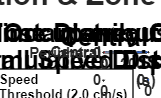

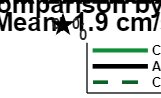

Figures saved successfully.


hold on;
plot(1, mean_speed_central, 'kp', 'MarkerSize',12, 'MarkerFaceColor','k');
plot(2, mean_speed_peripheral, 'kp', 'MarkerSize',12, 'MarkerFaceColor','k');
ylabel('Speed (cm/s)', 'FontWeight','bold');
title('Speed Comparison by Zone', 'FontSize',14, 'FontWeight','bold');
grid on; box on;

title(tiled2, sprintf('Spatial Trajectory & Zone-Specific Speed (Peripheral Width = %.1f cm)', peripheral_width_cm), ...
    'FontSize',16, 'FontWeight','bold');

%% Save high-quality figures
try
    saveas(fig1, sprintf('%s_locomotion_overview.fig', baseFilename));
    saveas(fig1, sprintf('%s_locomotion_overview.bmp', baseFilename), 'png');
    exportgraphics(fig1, sprintf('%s_locomotion_overview.pdf', baseFilename), 'ContentType','vector');

    saveas(fig2, sprintf('%s_spatial_zone_analysis.fig', baseFilename));
    saveas(fig2, sprintf('%s_spatial_zone_analysis.bmp', baseFilename), 'png');
    exportgraphics(fig2, sprintf('%s_spatial_zone_analysis.pdf', baseFilename), 'ContentType','vector');
    fprintf('Figures saved successfully.\n');
catch
    warning('Some figures could not be saved.');
end